% segmenting
block_size = 4;
block_perImg = (512/block_size)^2;
seg_assemble = zeros(block_perImg*100,block_size^2);
for k = 1:100
    img = fitsread("E:\学校事宜(7)\wb\ksvd+层次聚类图像重建wb\dataset_single\trainingset\ts ("+num2str(k)+").fits");
    seg = im2col(img,[block_size,block_size],'distinct')';
    seg_assemble(block_perImg*(k-1)+1:block_perImg*k,:) = seg;
end
badseg_assemble = zeros(block_perImg*100,block_size^2);
for k = 1:100
    img = fitsread("E:\学校事宜(7)\wb\ksvd+层次聚类图像重建wb\dataset_single\trainingset\ts ("+num2str(k)+").fits");
    img = imresize(img(1:2:end,1:2:end),[512,512],'bicubic');
    seg = im2col(img,[block_size,block_size],'distinct')';
    badseg_assemble(block_perImg*(k-1)+1:block_perImg*k,:) = seg;
end

% random pick trainging blocks
random_num = 50000;
indices = randperm(409600,random_num);
rand_seg = seg_assemble(indices,:);
badrand_seg = badseg_assemble(indices,:);
combined_seg = [rand_seg,badrand_seg];

% dist = pdist(rand_seg);
% dist_matrix = squareform(dist);
% cluster_matrix = linkage(dist,"average");
cluster_num = 5;
% T = cluster(cluster_matrix,'maxclust',cluster_num);
[idx,C] = kmeans(rand_seg,cluster_num);

% different classes
training_ceils = {};
for i = 1:cluster_num
    training_ceils{end+1} = combined_seg(idx==i,:);
end

% train
DICS = {};
BAD_DICS = {};
OUTPUTS = {};
redundancy = 1;     % 冗余度
SubImageSize = block_size;   % 分块图像的大小
K = redundancy*SubImageSize^2;
param.K = K;
param.numIteration = 20 ;   % KSVD迭代的次数

param.errorFlag = 1;    % 稀疏编码阶段不是使用固定稀疏系数，只有达到指定误差范围才停止迭代
param.errorGoal = 0.1;    % gamma
param.preserveDCAtom = 0;

% Pn = ceil(sqrt(K));     % 生产DCT基
% DCT = zeros(SubImageSize,Pn);
% for k=0:1:Pn-1
%     V=cos([0:1:SubImageSize-1]'*k*pi/Pn);
%     if k>0, V=V-mean(V); end
%     DCT(:,k+1)=V/norm(V);
% end
% DCT=kron(DCT,DCT);
% param.initialDictionary = DCT(:,1:param.K );    % 初始字典
% param.InitializationMethod =  'GivenMatrix';    % 由给定字典进行训练

param.InitializationMethod = 'DataElements';
for i = 1:cluster_num
    [Dictionary,output] = KSVD(training_ceils{i}',param);% KSVD训练字典
    DICS{end+1} = Dictionary(1:block_size^2,:);
    BAD_DICS{end+1} = Dictionary(block_size^2+1:end,:);
    OUTPUTS{end+1} = output;
end

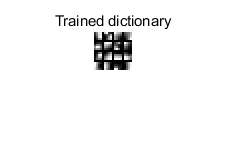

% sample show
dictimg = showdict(Dictionary(1:16,:),[1 1]*SubImageSize,4,4,'lines','highcontrast');
figure; imshow(imresize(dictimg,2,'nearest'));
title('Trained dictionary');

% RecMatrix = Dictionary*output.CoefMatrix;
% RecImage = col2im(RecMatrix,[8,8],[512,512],'distinct'); % 从列向量重建图像块

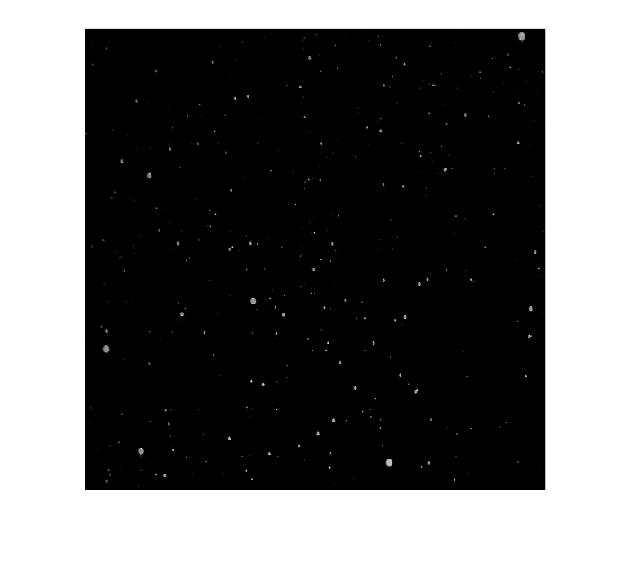

im = fitsread("E:\学校事宜(7)\wb\ksvd+层次聚类图像重建wb\dataset_single\testingset\02183_exp1_log_0_0.fits");
imshow(im)

% assign block to different class
im_seg = im2col(im,[block_size,block_size],'distinct')';
class = zeros(size(im_seg,1),1);
for i = 1:size(im_seg,1)
    [~, id] = min(sum((C-im_seg(i,:)).^2,2));
    class(i) = id;
end

% param.initialDictionary = BAD_DICS{1};
% [a,b]=KSVD(im_seg(1,:)',param)

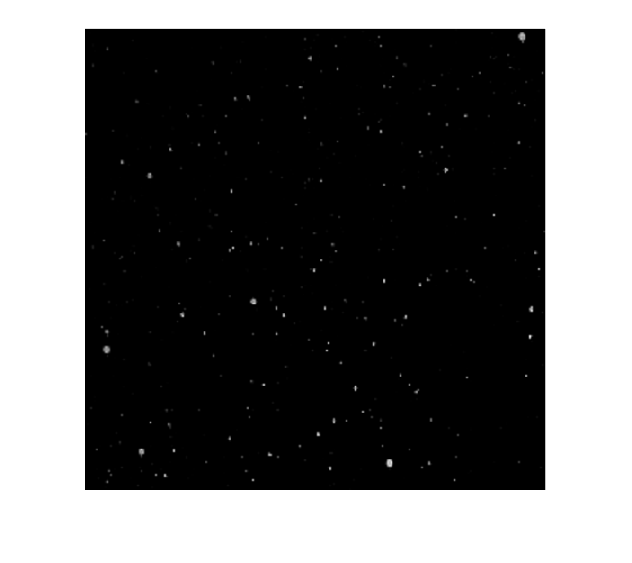

% downsampling & reconstruct
bad_im = imresize(im(1:2:end,1:2:end),[512,512],'bicubic');
imshow(bad_im)

% assign block to different class
badim_seg = im2col(bad_im,[block_size,block_size],'distinct')';
bad_class = zeros(size(badim_seg,1),1);
for i = 1:size(badim_seg,1)
    [~, id] = min(sum((C-badim_seg(i,:)).^2,2));
    bad_class(i) = id;
end

tabulate(bad_class) % statistics to ensure n > N

  Value    Count   Percent
      1    16084     98.17%
      2      162      0.99%
      3       45      0.27%
      4       42      0.26%
      5       51      0.31%


% block to reconstruct
spec = {};
for i = 1:cluster_num
    spec{end+1} = badim_seg(bad_class==i,:);
end

% sparse representation
sr = {};
for i = 1:cluster_num
    param.initialDictionary = BAD_DICS{i};
    param.numIteration = 50;
    [Dictionary,output] = KSVD(spec{i}',param);
    sr{end+1} = output;
end

% reconstruct
result = {};
for i = 1:cluster_num
    result{i} = DICS{i}*sr{i}.CoefMatrix;
end
R = zeros(size(badim_seg));
for i = 1:cluster_num
    R(bad_class==i,:) = result{i}';
end
RecMatrix = R';

psnr(im,im)

ans = Inf

psnr(bad_im,im)

ans = 33.5016

ssim(im,im)

ans = 1

ssim(bad_im,im)

ans = 0.9579

% [Dictionary,output] = KSVD(im_seg',param);
% RecMatrix=Dictionary*output.CoefMatrix;
RecImage = col2im(RecMatrix,[block_size,block_size],[512,512],'distinct'); % 从列向量重建图像块
imshow(RecImage)

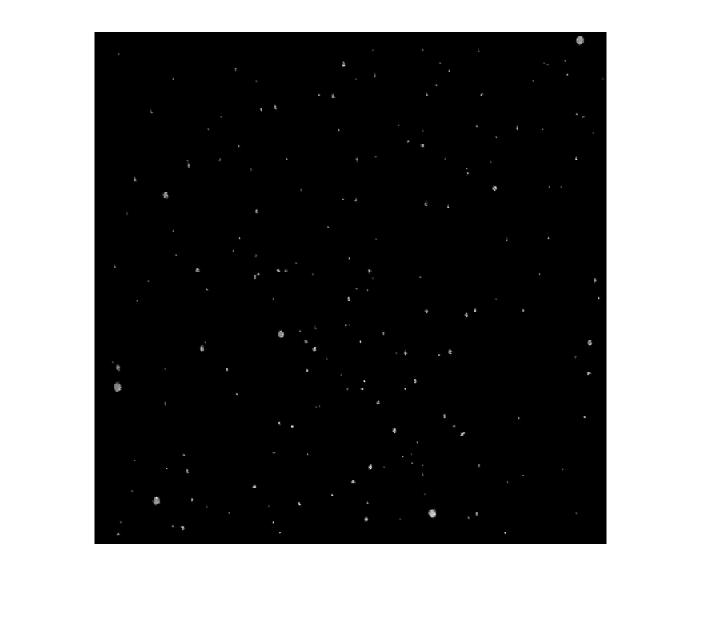

psnr(RecImage,im)

ssim(RecImage,im)

Psnr = zeros(14,1);

ans = 37.7561

SSIM = zeros(14,1);

ans = 0.9662

for c = 2:15
    disp(c)
    cluster_num = c;
    [idx,C] = kmeans(rand_seg,cluster_num);
    training_ceils = {};
    for i = 1:cluster_num
        training_ceils{end+1} = combined_seg(idx==i,:);
    end
    flag = 0;
    for i = 1:cluster_num
        if size(training_ceils{i},1)<32
            flag = 1;
            break;
        end
    end
    if flag == 1
        continue
    end
    DICS = {};
    BAD_DICS = {};
    OUTPUTS = {};
    redundancy = 1;     % 冗余度
    SubImageSize = block_size;   % 分块图像的大小
    K = redundancy*SubImageSize^2;
    param.K = K;
    param.numIteration = 20 ;   % KSVD迭代的次数
    
    param.errorFlag = 1;    % 稀疏编码阶段不是使用固定稀疏系数，只有达到指定误差范围才停止迭代
    param.errorGoal = 0.1;    % gamma
    param.preserveDCAtom = 0;
    
    param.InitializationMethod = 'DataElements';
    for i = 1:cluster_num
        [Dictionary,output] = KSVD(training_ceils{i}',param);% KSVD训练字典
        DICS{end+1} = Dictionary(1:block_size^2,:);
        BAD_DICS{end+1} = Dictionary(block_size^2+1:end,:);
        OUTPUTS{end+1} = output;
    end
    
    bad_class = zeros(size(badim_seg,1),1);
    for i = 1:size(badim_seg,1)
        [~, id] = min(sum((C-badim_seg(i,:)).^2,2));
        bad_class(i) = id;
    end
    
    stat = tabulate(bad_class);
    if sum(stat(:,2)>=16) < c
        continue
    end

    spec = {};
    for i = 1:cluster_num
        spec{end+1} = badim_seg(bad_class==i,:);
    end
    sr = {};
    for i = 1:cluster_num
        param.initialDictionary = BAD_DICS{i};
        param.numIteration = 50;
        [Dictionary,output] = KSVD(spec{i}',param);
        sr{end+1} = output;
    end
    result = {};
    for i = 1:cluster_num
        result{i} = DICS{i}*sr{i}.CoefMatrix;
    end
    R = zeros(size(badim_seg));
    for i = 1:cluster_num
        R(bad_class==i,:) = result{i}';
    end
    RecMatrix = R';
    rec_img = col2im(RecMatrix,[block_size,block_size],[512,512],'distinct');
    Psnr(c-1) = psnr(rec_img,im);
    SSIM(c-1) = ssim(rec_img,im);
end

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15



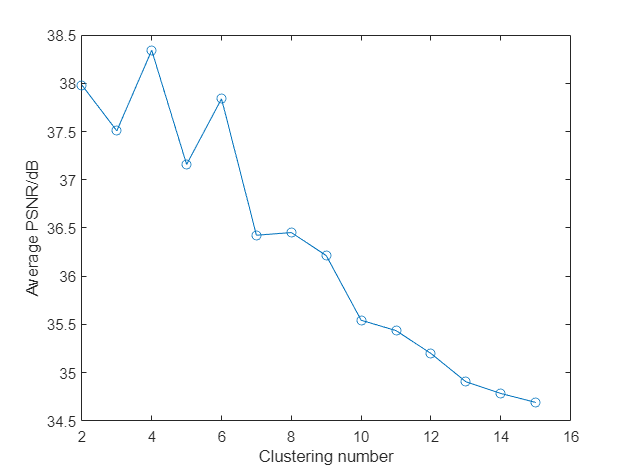

figure
plot(2:15,Psnr,'o-')
ylabel('Average PSNR/dB')
xlabel('Clustering number')

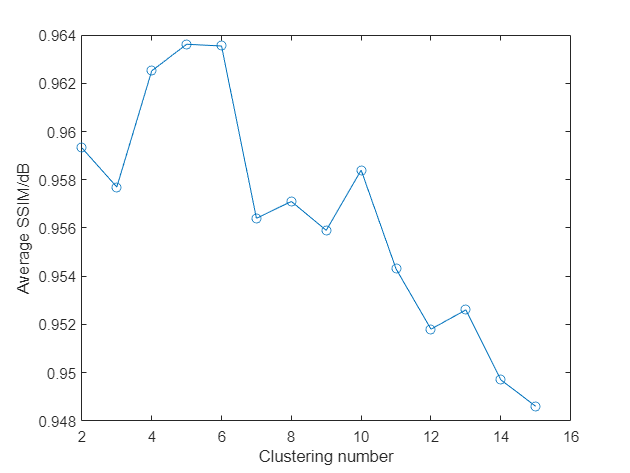

figure
plot(2:15,SSIM,'o-')
ylabel('Average SSIM/dB')
xlabel('Clustering number')

Psnr_g = zeros(10,1);
SSIM_g = zeros(10,1);
t = 1;
cluster_num = 4;
[idx,C] = kmeans(rand_seg,cluster_num);
training_ceils = {};
for i = 1:cluster_num
    training_ceils{end+1} = combined_seg(idx==i,:);
end
for gamma = 0.01:0.11:1
    disp(gamma)
    
    DICS = {};
    BAD_DICS = {};
    OUTPUTS = {};
    redundancy = 1;     % 冗余度
    SubImageSize = block_size;   % 分块图像的大小
    K = redundancy*SubImageSize^2;
    param.K = K;
    param.numIteration = 20 ;   % KSVD迭代的次数
    
    param.errorFlag = 1;    % 稀疏编码阶段不是使用固定稀疏系数，只有达到指定误差范围才停止迭代
    param.errorGoal = gamma;    % gamma
    param.preserveDCAtom = 0;
    
    param.InitializationMethod = 'DataElements';
    for i = 1:cluster_num
        [Dictionary,output] = KSVD(training_ceils{i}',param);% KSVD训练字典
        DICS{end+1} = Dictionary(1:block_size^2,:);
        BAD_DICS{end+1} = Dictionary(block_size^2+1:end,:);
        OUTPUTS{end+1} = output;
    end
    
    bad_class = zeros(size(badim_seg,1),1);
    for i = 1:size(badim_seg,1)
        [~, id] = min(sum((C-badim_seg(i,:)).^2,2));
        bad_class(i) = id;
    end

    spec = {};
    for i = 1:cluster_num
        spec{end+1} = badim_seg(bad_class==i,:);
    end
    sr = {};
    for i = 1:cluster_num
        param.initialDictionary = BAD_DICS{i};
        param.numIteration = 50;
        [Dictionary,output] = KSVD(spec{i}',param);
        sr{end+1} = output;
    end
    result = {};
    for i = 1:cluster_num
        result{i} = DICS{i}*sr{i}.CoefMatrix;
    end
    R = zeros(size(badim_seg));
    for i = 1:cluster_num
        R(bad_class==i,:) = result{i}';
    end
    RecMatrix = R';
    rec_img = col2im(RecMatrix,[block_size,block_size],[512,512],'distinct');
    Psnr_g(t) = psnr(rec_img,im);
    SSIM_g(t) = ssim(rec_img,im);
    disp('over')
    t = t + 1;
end

    0.0100



over


    0.1200



over


    0.2300



over


    0.3400



over


    0.4500



over


    0.5600



over


    0.6700



over


    0.7800



over


    0.8900



over


     1



over


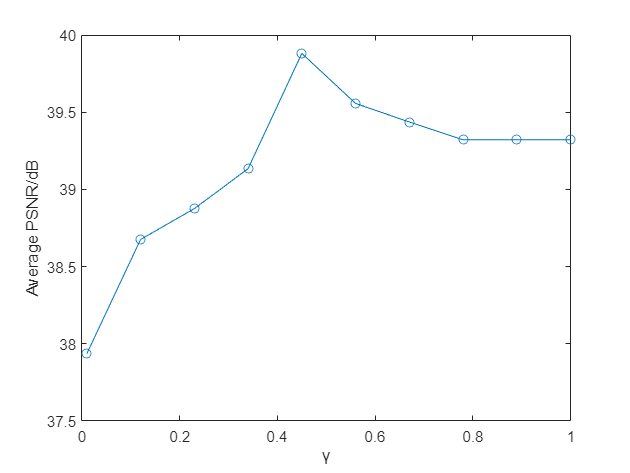

figure
plot(0.01:0.11:1,Psnr_g,'o-')
ylabel('Average PSNR/dB')
xlabel('\gamma')

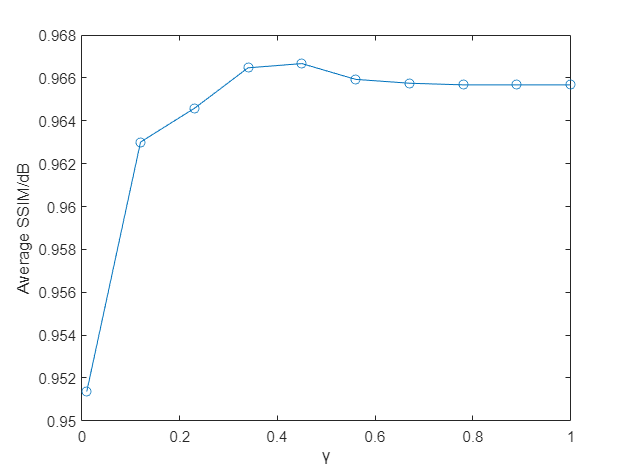

figure
plot(0.01:0.11:1,SSIM_g,'o-')
ylabel('Average SSIM/dB')
xlabel('\gamma')

tic
cluster_num = 4;
[idx,C] = kmeans(rand_seg,cluster_num);
training_ceils = {};
for i = 1:cluster_num
    training_ceils{end+1} = combined_seg(idx==i,:);
end

redundancy = 1;     % 冗余度
SubImageSize = block_size;   % 分块图像的大小
K = redundancy*SubImageSize^2;
param.K = K;
param.numIteration = 20 ;   % KSVD迭代的次数
    
param.errorFlag = 1;    % 稀疏编码阶段不是使用固定稀疏系数，只有达到指定误差范围才停止迭代
param.errorGoal = gamma;    % gamma
param.preserveDCAtom = 0;
    
param.InitializationMethod = 'DataElements';
for i = 1:cluster_num
    [Dictionary,output] = KSVD(training_ceils{i}',param);% KSVD训练字典
    DICS{end+1} = Dictionary(1:block_size^2,:);
    BAD_DICS{end+1} = Dictionary(block_size^2+1:end,:);
    OUTPUTS{end+1} = output;
end
    
bad_class = zeros(size(badim_seg,1),1);
for i = 1:size(badim_seg,1)
    [~, id] = min(sum((C-badim_seg(i,:)).^2,2));
    bad_class(i) = id;
end

spec = {};
for i = 1:cluster_num
    spec{end+1} = badim_seg(bad_class==i,:);
end
sr = {};
for i = 1:cluster_num
    param.initialDictionary = BAD_DICS{i};
    param.numIteration = 50;
    [Dictionary,output] = KSVD(spec{i}',param);
    sr{end+1} = output;
end
result = {};
for i = 1:cluster_num
    result{i} = DICS{i}*sr{i}.CoefMatrix;
end
R = zeros(size(badim_seg));
for i = 1:cluster_num
    R(bad_class==i,:) = result{i}';
end
RecMatrix = R';
rec_img = col2im(RecMatrix,[block_size,block_size],[512,512],'distinct');
toc

历时 6.629927 秒。
